# **Equações Diferenciais De Ordem Superior: *****Solução Com Espaço De Estados No MATLAB***

### ***RESOLUÇÃO DO TRABALHO II***

## Primeira Equação:

#### 
$$$$ -3\ddot{y} + 4\dot{y} + x = 0 $$$$


Resolvendo, temos o seguinte sistema:

#### 
$$$$ \begin{cases}
\dot{x_1} = x_2 \\
\dot{x_2} = \frac{1}{3}(4x_2 + x_1)
\end{cases}$$

$$
 

% definindo a função para o sistema da primeira equação
function x_ponto=edo1(~, x)
    x_ponto = [0;0];
    x_ponto(1) = x(2);
    x_ponto(2)=(4*x(2)+x(1))./3;
end

Agora, encontrando a solução e plotando o gráfico:

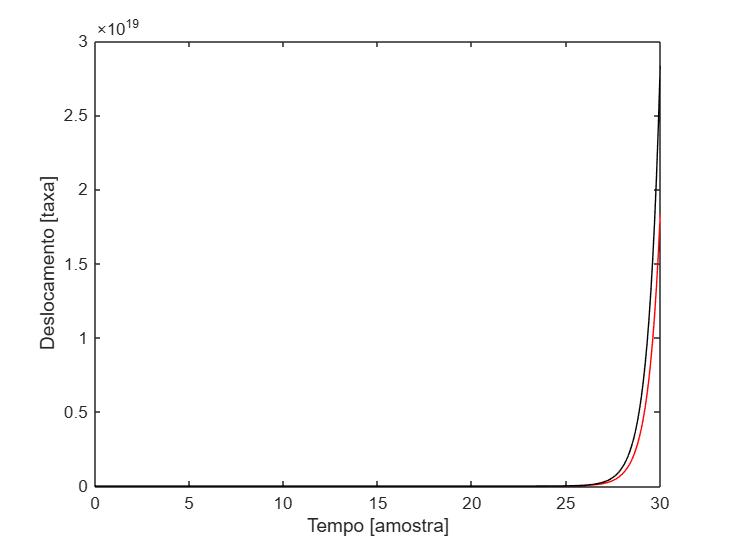

% calculando a edos
[t, x] = ode45(@edo1, 0:0.1:30, [1; 0]);

% armazenando resultados
tempo = t;
col1 = x(:,1);
col2 = x(:,2);

% gráficos dos resultados
plot(tempo, col1, 'r');
xlabel('Tempo [amostra]');
ylabel('Deslocamento [taxa]');
hold on
plot(tempo, col2, 'k');
xlabel('Tempo [amostra]');
ylabel('Deslocamento [taxa]');
hold off

## Segunda Equação:

#### 
$$$$ -\frac{1}{4}\ddot{y} - 3\dot{y} = 0 $$$$


Resolvendo, temos o seguinte sistema:

#### 
$$$$ \begin{cases}
\dot{x_1} = x_2 \\
\dot{x_2} = -12x_2
\end{cases}$$$$
 

% definindo a função para o sistema da segunda equação
function x_ponto=edo2(~, x)
    x_ponto = [0;0];
    x_ponto(1) = x(2);
    x_ponto(2)=-12.*x(2);
end

Agora, encontrando a solução e plotando o gráfico:

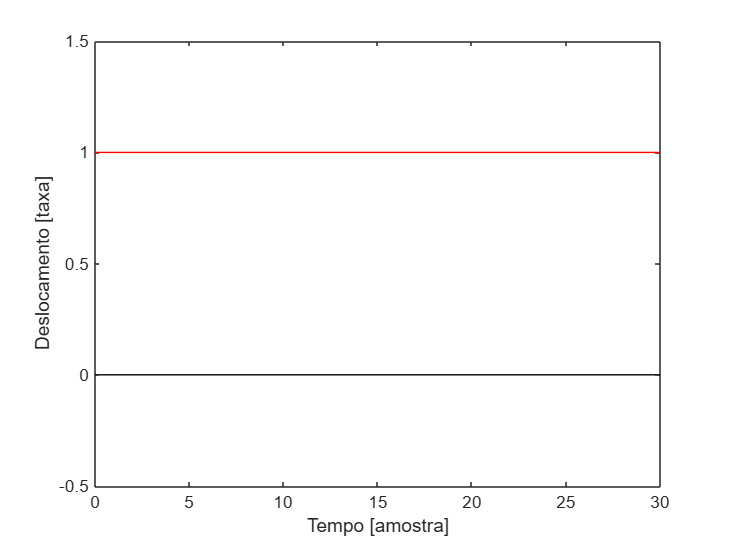

% calculando a edos
[t, x] = ode45(@edo2, 0:0.1:30, [1; 0]);

% armazenando resultados
tempo = t;
col1 = x(:,1);
col2 = x(:,2);

% gráficos dos resultados
plot(tempo, col1, 'r');
xlabel('Tempo [amostra]');
ylabel('Deslocamento [taxa]');
ylim([-1 1]);
hold on
plot(tempo, col2, 'k');
xlabel('Tempo [amostra]');
ylabel('Deslocamento [taxa]');
ylim([-0.5 1.5]);
hold off

## Terceira Equação:

#### 
$$$$ 5\ddot{y} + 15 = 0 $$$$


Resolvendo, temos o seguinte sistema:

#### 
$$$$ \begin{cases}
\dot{x_1} = x_2 \\
\dot{x_2} = -3
\end{cases}$$

$$
 

% definindo a função para o sistema da terceira equação
function x_ponto=edo3(~, x)
    x_ponto = [0;0];
    x_ponto(1) = x(2);
    x_ponto(2) = -3;
end

Agora, encontrando a solução e plotando o gráfico:

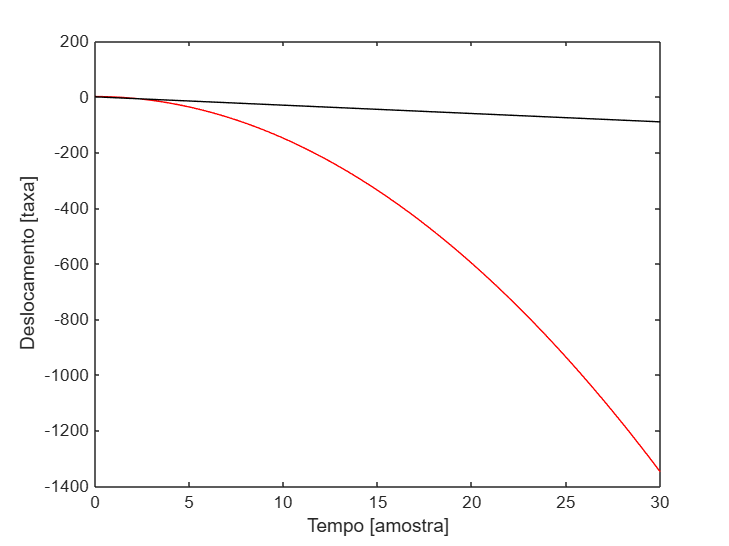

% calculando a edos
[t, x] = ode45(@edo3, 0:0.1:30, [1; 0]);

% armazenando resultados
tempo = t;
col1 = x(:,1);
col2 = x(:,2);

% gráficos dos resultados
plot(tempo, col1, 'r');
xlabel('Tempo [amostra]');
ylabel('Deslocamento [taxa]');
hold on
plot(tempo, col2, 'k');
xlabel('Tempo [amostra]');
ylabel('Deslocamento [taxa]');
hold off